T      = 4;                       % period of the periodic extension
kMax   = 30;                      % highest positive harmonic
k      = -kMax:kMax;              % vector of harmonic indices
Nt     = 8001;                    % # time samples for numerical integral
t      = linspace(-T/2, T/2, Nt); % integration grid (covers one period)
sincf  = @(x) sin(pi*x)./(pi*x);  % MATLAB's 'sinc' with normalised pi


xt_gauss   = exp(-t.^2);
ck_dir_g   = (1/T) * trapz(t, xt_gauss .* exp(-1j*2*pi*(k.'/T).*t) , 2).';

ck_ctft_g  = (sqrt(pi)/T) .* exp(-(pi^2) * (k/T).^2);

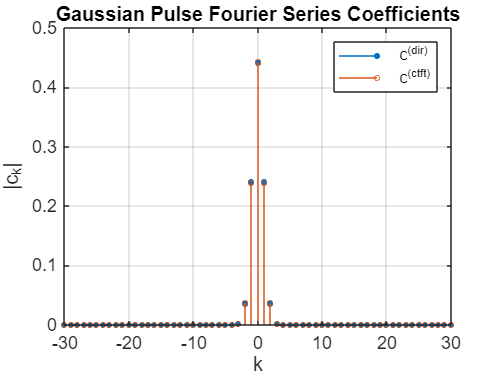

figure(1);
stem(k, abs(ck_dir_g), 'filled','MarkerSize',3); hold on
stem(k, abs(ck_ctft_g), 'o','MarkerSize',3);
title('Gaussian Pulse Fourier Series Coefficients');  xlabel('k');  ylabel('|c_k|');
legend('c^{(dir)}','c^{(ctft)}');  grid on

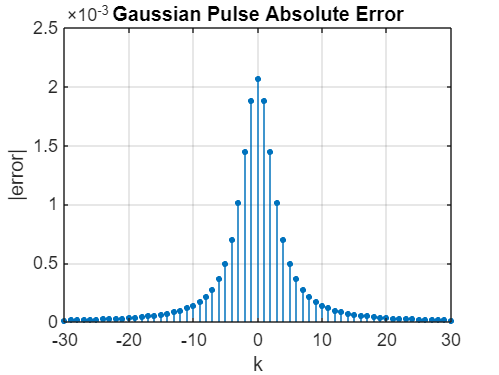


figure(2);
stem(k, abs(ck_dir_g - ck_ctft_g), 'filled','MarkerSize',3);
title('Gaussian Pulse Absolute Error');  xlabel('k');  ylabel('|error|');
grid on

win        = double(abs(t) < 1);
xt_sine    = sin(2*pi*t) .* win;
ck_dir_s   = (1/T) * trapz(t, xt_sine .* exp(-1j*2*pi*(k.'/T).*t) , 2).';

f_samp     = k / T;
X_samp     = (1./(1j)) .* ( sincf( 2*(f_samp-1) ) - sincf( 2*(f_samp+1) ) );
ck_ctft_s  = (1/T) * X_samp;

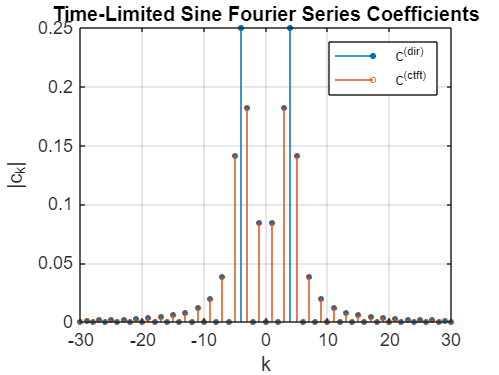

figure(3);
stem(k, abs(ck_dir_s), 'filled','MarkerSize',3); hold on
stem(k, abs(ck_ctft_s), 'o','MarkerSize',3);
title('Time-Limited Sine Fourier Series Coefficients');  xlabel('k');  ylabel('|c_k|');
legend('c^{(dir)}','c^{(ctft)}');  grid on

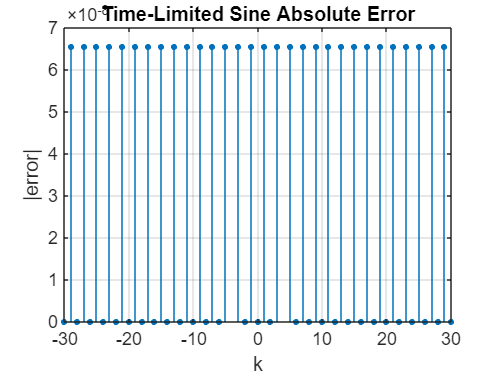


figure(4);
stem(k, abs(ck_dir_s - ck_ctft_s), 'filled','MarkerSize',3);
title('Time-Limited Sine Absolute Error');  xlabel('k');  ylabel('|error|');
grid on